## Splines (when lsf polynomials fails...)

**Example. **Let us consider the function

$f(x) = \frac{1}{1+25x^2}$,

on the interval $-1\le x\le 1$, and a sample of points given by the abscisses $x_{i} = -1 + 0.2(i-1)$, and their corresponding values $y=f(y_{i})$, $i=1,\dots,N=11$.

clearvars
close all

f = @(x) 1./(1+25*x.^2); %Runge phenomenon....
a = -1; b = 1; numSamplePoints = 11; degree = 2;

h = (b-a)/(numSamplePoints-1);

%Table
dataX = -1:h:1;
dataY= f(dataX);

%Points we shall use to plot
delta=0.01;
x = a:delta:b;
y = f(x);
%numPlotPoints = floor((b-a)/delta)+1;
%x = linspace(a,b,numPlotPoints);


### Cubic Splines

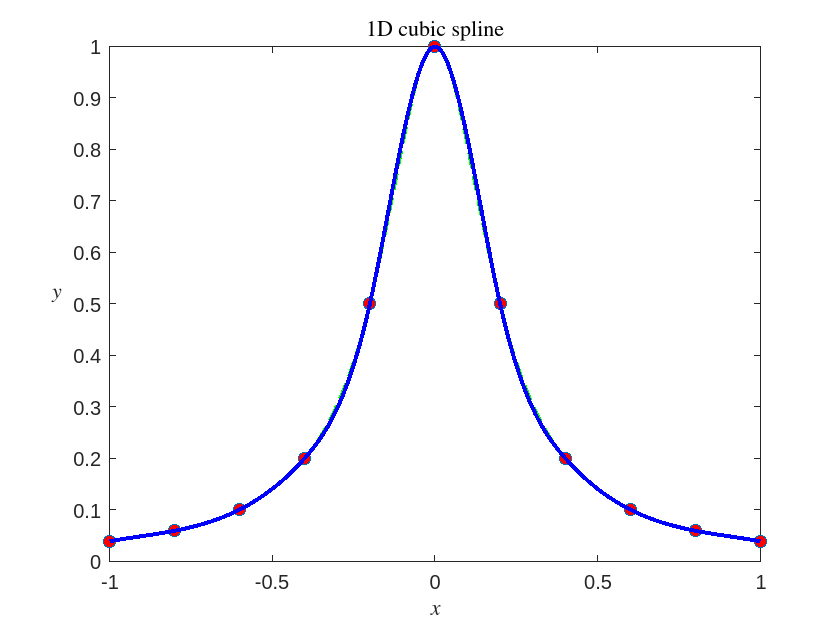


%Plot sample
plot(dataX, dataY, 'o', 'MarkerFaceColor','red', 'MarkerSize', 6)
hold on
plot(x,y,'--','color','green','LineWidth',1);

%cubic spline
yCubicSpline = spline(dataX,dataY,x);

plot(x, yCubicSpline,'-','Color','blue','LineWidth', 2)
set(gcf,'defaultTextInterpreter','LaTeX')
title('1D cubic spline')
xlabel('$$x$$')
ylabel('$$y\quad$$','rot',360)
hold off

### Linear spline

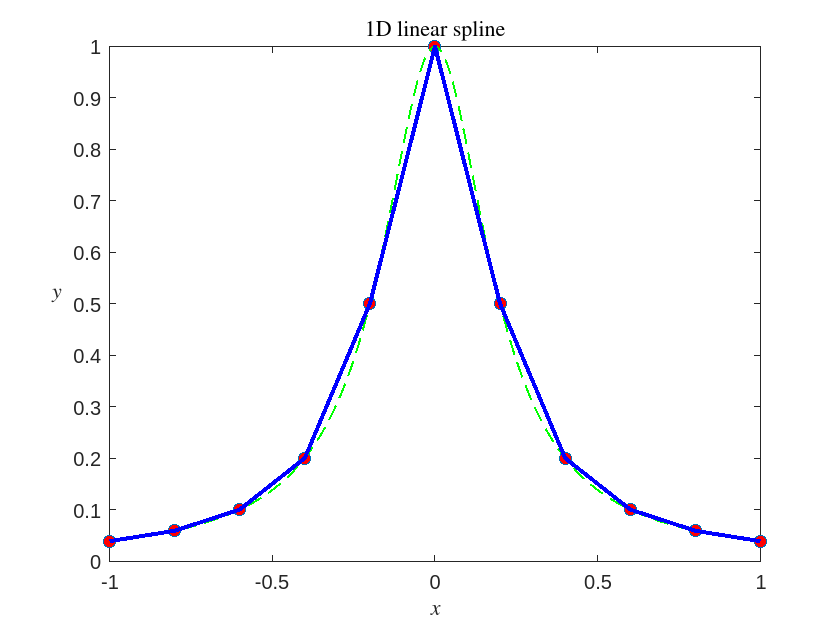

%Plot sample
plot(dataX, dataY, 'o', 'MarkerFaceColor','red', 'MarkerSize', 6)
hold on
plot(x,y,'--','color','green','LineWidth',1);

%cubic spline
yLinearSpline = interp1(dataX,dataY,x);

plot(x, yLinearSpline,'-','Color','blue','LineWidth', 2)
title('1D linear spline')
xlabel('$$x$$')
ylabel('$$y\quad$$','rot',360)
hold off